# Reconeixement

## Training

% Define the base folder path
baseFolder = './Train/';

% Get all subfolders matching the pattern
folderPattern = fullfile(baseFolder, '*', 'TM');
folders = dir(folderPattern);

% Initialize a structure to store features for each model
modelFeatures = struct();

% Loop through each folder
for i = 1:length(folders)
    % Get the current folder and model name
    currentFolder = fullfile(folders(i).folder, folders(i).name);
    
    % Extract the name of the folder before "TM"
    [parentPath, ~, ~] = fileparts(currentFolder); % Get parent path
    [modelName, ~,~] = fileparts(parentPath);        % Get folder name before "TM"
    [~,modelName,~] = fileparts(modelName); 
    modelName = strrep(modelName," ","_");

    % Initialize storage for the current model
    modelFeatures.(modelName).keypoints = {};
    modelFeatures.(modelName).rgHistograms = {};
    modelFeatures.(modelName).rgMin = {};
    modelFeatures.(modelName).im = {};
    
    % Get all images in the current folder
    imageFiles = dir(fullfile(parentPath, '*.jpg')); % Adjust extension if needed
    
    % Process each image
    for j = 1:length(imageFiles)
        % Get the image file path and load it
        imagePath = fullfile(imageFiles(j).folder, imageFiles(j).name);
        img = imread(imagePath);
        
        % Convert image to grayscale for keypoint detection
        grayImg = rgb2gray(img);
        
        % Extract keypoints (using SURF as an alternative to SIFT)
        keypoints = detectSIFTFeatures(grayImg);
        modelFeatures.(modelName).keypoints{end+1} = keypoints.Location; % Store keypoints
        
        % Compute the normalized RG histogram
        % Normalize RGB values
        img = im2double(img); % Ensure values are in [0, 1]
        R = img(:, :, 1);
        G = img(:, :, 2);
        B = img(:, :, 3);
        RG = R ./ (R + G + B + eps); % Avoid division by zero
        GG = G ./ (R + G + B + eps); % Avoid division by zero
        
        % Compute histogram
        numBins = 16; % Adjust number of bins as needed
        [rgHist, ~] = hist3([RG(:), GG(:)], [numBins, numBins]);
        
        % Normalize histogram
        rgHist = rgHist / sum(rgHist(:));
        modelFeatures.(modelName).rgHistograms{end+1} = rgHist;
        modelFeatures.(modelName).im{end+1} = img;
    end
    [~,t] = size(modelFeatures.(modelName).rgHistograms);
    blanket = ones(numBins)*255;
    for k = 1:t
        A = modelFeatures.(modelName).rgHistograms{k};
        blanket = min(blanket, A);
    end
    
    mx = double(1/max(max(blanket)));
    blanket = blanket.*mx;
    modelFeatures.(modelName).rgMin{end+1} = blanket;

end

% Display results
disp('Keypoints and normalized RG histograms extracted and labeled by model.');

Keypoints and normalized RG histograms extracted and labeled by model.


## Mostres 

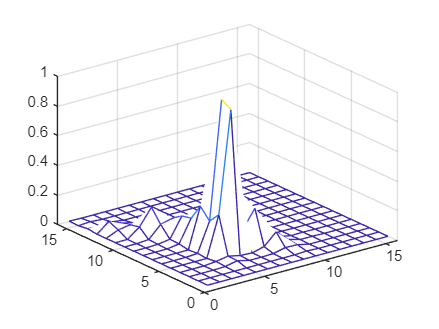

figure,mesh(modelFeatures.pokemon.rgMin{1})

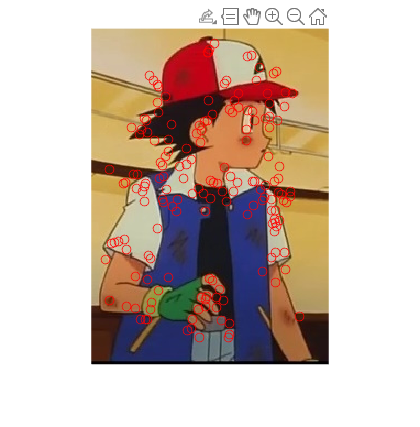

figure,imshow(modelFeatures.pokemon.im{1})
hold on;
keys = modelFeatures.pokemon.keypoints{1};
keysx = keys(:,1);
keysy = keys(:,2);
plot(keysx,keysy,"ro");